# **Welcome to the Cartoon Filter!**

This time we're going to create a filter to give a cartoonish effect to any image we want, and how? With some basic Image Processing :D

The general process can be summarized into the following steps:

- **Loading** the image

- Defining and a applying an **Anisotropic Diffusion filter**

- Mean Shift **Clustering** of the colors in the filtered image

- **Replacing the colors** in the filtered image with the new color mapping from the clusters

- **Recovering borders** and adding them do the filtered image

- Profit

First of all, our always appreciated clearing of variables and loading the image

clear variables; clc; close all;
file = uigetimagefile;
im = imread(file);

Now we resize for simplicity and faster execution times ***(to be removed in final version)***

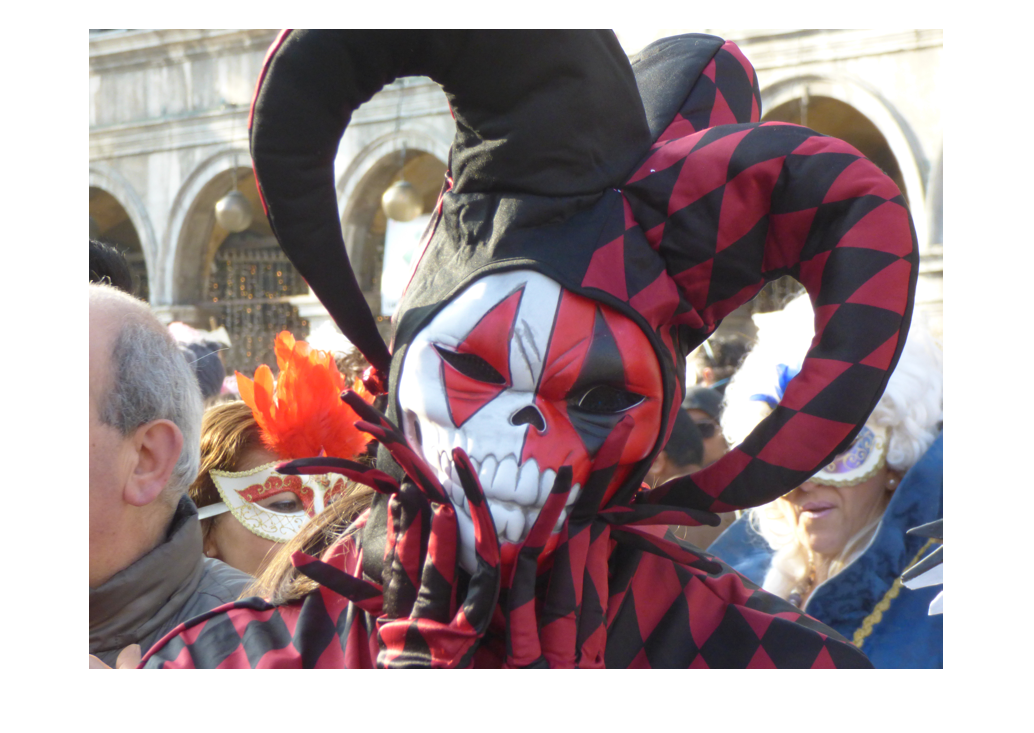

im_small = imresize(im,[640 NaN],"AntiAliasing",true);
[m,n,n_colors] = size(im_small);
imshow(im_small);

We select the parameters for the Anisotropic Difussion

K = 15;
T = 30;

And now apply it to `image ``im_small`

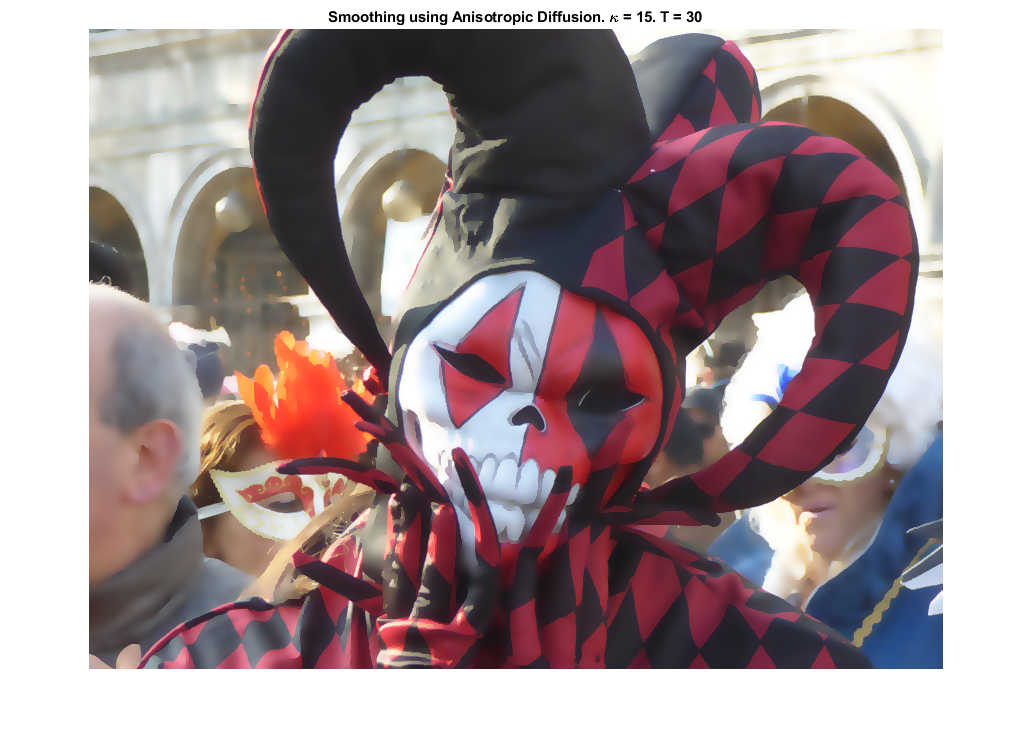

im_smooth = im_small;
for i = 1:n_colors   
    im_smooth(:,:,i) = imdiffusefilt(im_small(:,:,i),"GradientThreshold",K,"NumberOfIterations",T);
end
imshow(im_smooth);
% montage({A,B});
title(['Smoothing using Anisotropic Diffusion. \kappa = ' num2str(K) '. T = ' num2str(T)])

With the smoothed image, it is time to cluster the colors in it to give it a more basic color palette, as in a comic book.

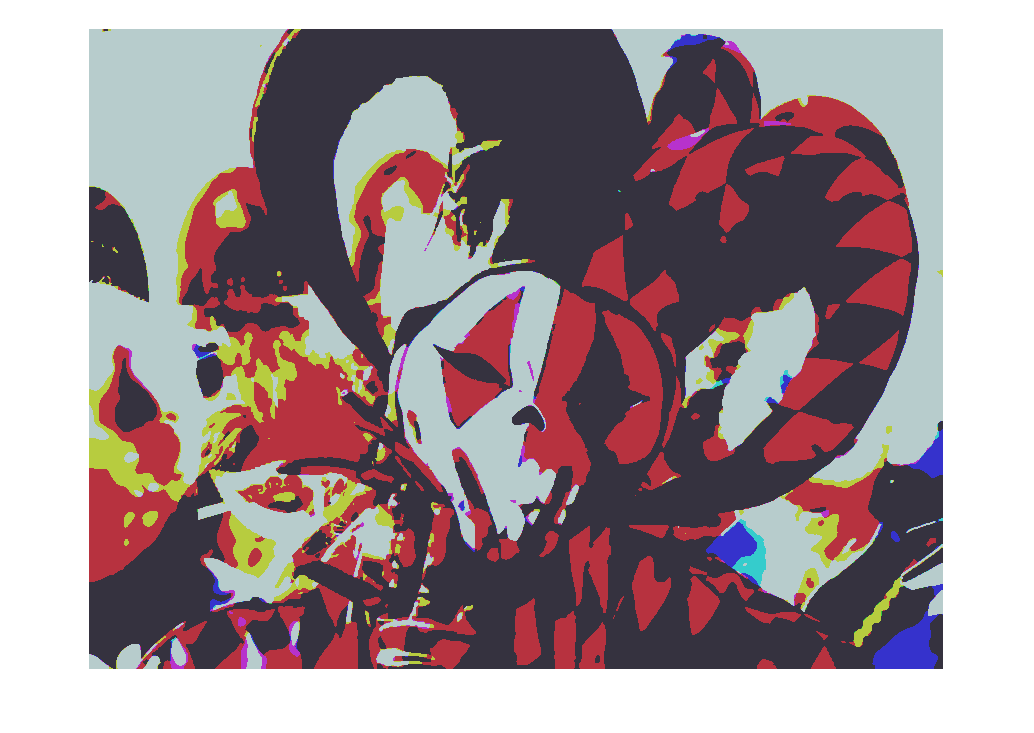

n_clusters = 2;
im_clustered = double(im_smooth);
for i = 1:n_colors
    aux = im_clustered(:,:,i);
    [idx3,C,sumdist3] = kmeans(aux(:),n_clusters,'Distance','cityblock');
    im_clustered(:,:,i) = reshape(C(idx3),m,[]);
end

imshow(im_clustered/255)

**Alternative version** with my own implementation of the `Anisotropic Diffusion`

lambda = 0.25;
B = anisotropicDiffusion(A,lambda,K,T);
B = uint8(B);
imshow(B);